defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Figure 3 - Calcium Imaging']);

%data
Confiles = loadFileList('.\Data\WT_vs_KO\WT\*.mat');
KOfiles = loadFileList('.\Data\WT_vs_KO\KO\*.mat');

WTareas = []; KOareas = [];
WTdata = table();
%load data and analyze
for i = 1:size(Confiles,1)
    load(Confiles{i})
    WTdata = [WTdata; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    WTareas = [WTareas; Crens.areas];
end
WTdata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

KOdata = table();
for i = 1:size(KOfiles,1)
    load(KOfiles{i})
    KOdata = [KOdata; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    KOareas = [KOareas; Crens.areas];
end
KOdata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};


dim = [1.2 1.5];

[h, p] = compare2(WTdata.CrenFreq, KOdata.CrenFreq, {'WT', 'KO',},'Crenations per minute', dim,[5 12]);

   2.7119e-06



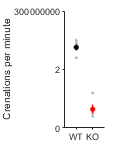

figure(h)
ylim([0 4])
yticks([0:2:4])
yticklabels({'0','2','300000000'})
figQuality(gcf, gca, dim);
%print('.\EPS Panels\CrenFreq.pdf','-dpdf');
export_fig('.\EPS Panels\CrenFreq.eps',gcf);


[h, p] = compare2(WTdata.CrenArea, KOdata.CrenArea,{'WT', 'KO'}, 'Crenation Area', dim,[5 12]);

   1.4097e-06



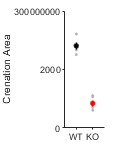

figure(h)
ylim([0 4000]);
yticks([0:2000:4000]);
yticklabels({'0','2000','300000000'})
figQuality(gcf, gca, dim);
export_fig('.\EPS Panels\CrenArea.eps',gcf);

%%example
file = loadFileList('.\Data\WT_vs_KO\WT\*.mat');
file = file{1};
load(file);
[h, h2] = drawCaEvents(Crens.crenationImg,Crens.locs,600,Crens.baseImg)

h =   Figure (31) with properties:

      Number: 31
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [937 954 686 349]
       Units: 'pixels'

  Show all properties


h2 =   Figure (32) with properties:

      Number: 32
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


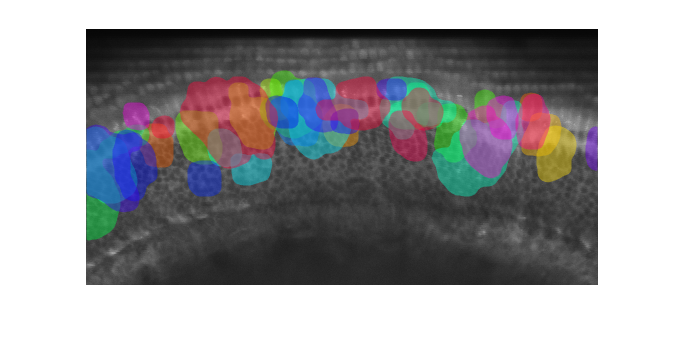

figure(h);
print('.\EPS Panels\WT_Ca2.pdf','-dpdf');

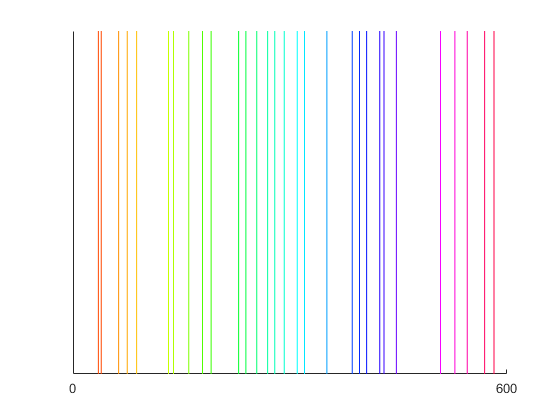

figure(h2);
print('.\EPS Panels\WT_Ca2_ticks.pdf','-dpdf');

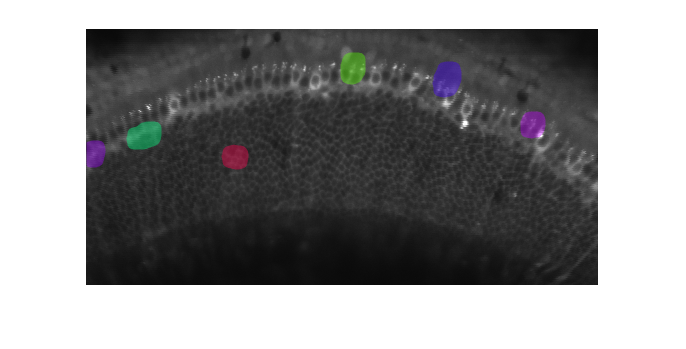


%%example
file = loadFileList('.\Data\WT_vs_KO\KO\*.mat');
file = file{4};
load(file);
[h, h2] = drawCaEvents(Crens.crenationImg,Crens.locs,600,Crens.baseImg);
figure(h);
print('.\EPS Panels\KO_Ca2.pdf','-dpdf');

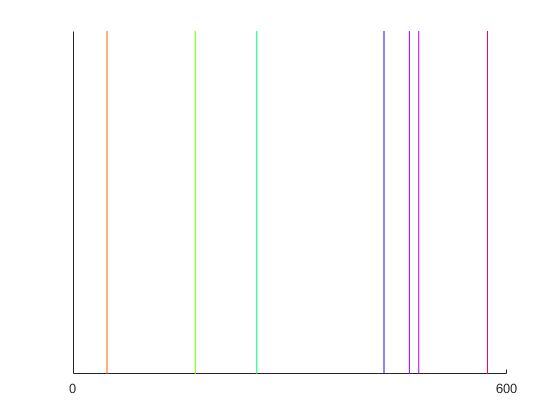

figure(h2);
print('.\EPS Panels\KO_Ca2_ticks.pdf','-dpdf');